# Convolution (and upsampling)

This function implements a disrete convolution between a symbol stream and the impulse response of the TX filter (i.e., the pulse shape). To do so, the symbol stream is first upsampled in order to match the sampling rate defined by the pulse IR, and then the discrete convolution is performed).

**Inputs:**

- *symb_TX*: complex symbol stream vector of size *nb_symb x 1* where *nb_symb = *length( *symb_TX *)

- *g*: Impulse Response (IR) of the pulse of size *1 x *length( *g* )

- *sps*: number of samples per symbol 

**Ouput:**

- *signal*: result of the convolution, vector of size *[ ( nb_symb - 1 ) * sps + length( g ) ] x 1*

function signal = convolution_TX( symb_TX , g , sps )

## Upsampling

In order to match the sampling rate used to design the filter impulse response *g*, the symbol vector *symb_TX *must first be upsampled as illustrated below (zero-padding):

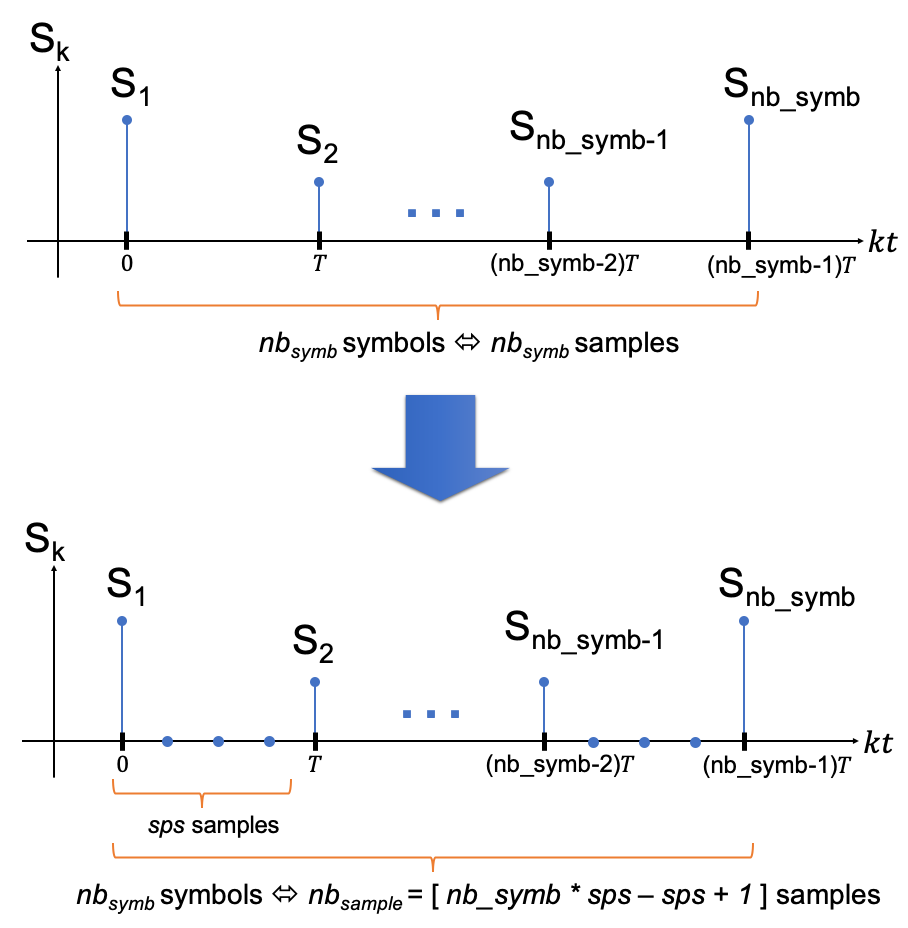

% Upsampling by a factor sps: insert (sps-1) zeros between successive symbols
nb_symb   = length( symb_TX ) ;
signal_up = zeros( nb_symb * sps , 1 ) ;
signal_up( 1 : sps : end ) = symb_TX ;

## Discrete Convolution

The discrete convolution between the upsampled symbol stream $ s_{up}$ and the filter Impulse Response (IR) $g$ is defined as $\left( s_{up} * g \right)[n]=\sum_{l=-\infty}^{+\infty}s_{up}[n-l]g[l]$. In our case, $g$ represents the filter Impulse Response (IR) which is finite (FIR filter). So the convolution can be written as a finite summation: 


$$\left( s_{up} * g \right)[n]=\sum_{l=-L}^{L}s_{up}[n-l]g[l]$$


with $n \in [1 : nb_{sample}]$ and $2L+1$ is the number of samples of the filter IR.

 To implement this finite summation in Matlab, a special care to vector indexes should be observed. Indeed, Matlab does not handle negative indexes. So the summation should be coded as:


$$\left( s_{up} * g \right)[n]=\sum_{l=-L}^{L}s_{up}[n-l]g[l+L+1]$$


An issue also raises when:

- $n\leq l$: indexes become negative in $ s_{up}$ 

- $n - l>nb_{sample}$: indexes exceed the number of elements in $ s_{up}$

 To avoid that, it is possible to fill the $ s_{up}$ vector with $2L$ zeros at the begining and $2L$ zeros at the end such as:

$ s^{filled}_{up}=[ 0~\cdots~0~s_{up}~0~\cdots~0]$. The convolution to implement becomes then:


$$\left(  s^{filled}_{up} * g \right)[n]=\sum_{l=-L}^{L} s^{filled}_{up}[n-l]g[l+L+1]$$


with $n \in [L+1 : nb_{sample}+3L]$.

% Discrete convolution of the upsampled symbol stream with the pulse g
% y[n] = sum_k g[k] * signal_up[n-k]
Lg    = length( g ) ;
Nx    = length( signal_up ) ;
y_tmp = zeros( Nx + Lg - 1 , 1 ) ;
g_col = g(:) ;
for n = 1 : Nx
    y_tmp( n : n + Lg - 1 ) = y_tmp( n : n + Lg - 1 ) + signal_up( n ) * g_col ;
end

### Vector cropping

The vector resulting from the convolution of the filter IR and the symbol stream contains zeros at its begining and its end. They should be removed to obtain the appropriate vector size of *[ ( nb_symb - 1 ) * sps + length( g ) ] x 1*.

% The convolution produces a vector of length Nx + Lg - 1.
% The expected signal length is (nb_symb-1)*sps + length(g), so the last
% (sps-1) trailing samples (coming from the zeros padded at the end of the
% upsampled vector) are discarded.
signal = y_tmp( 1 : (nb_symb - 1)*sps + Lg ) ;

The size of the resulting signal, is equal to the upsampled stream PLUS the filter length - 1. There is therefore a tail at the begining and the end of the time domain vector introduced by the filter delay.

end